# Negative binomial distribution fit to spiking data

% load data
dat = readtable('example-data.csv');

## plot histogram of spike counts

As you can see from this histogram, spike counts vary considerably across different trials. 

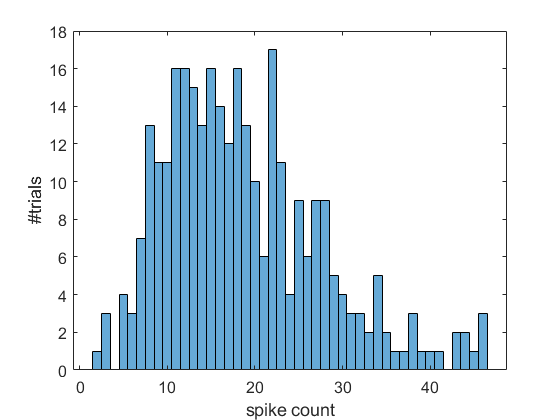

figure(1),clf
histogram(dat.count)
xlabel('spike count')
ylabel('#trials')

## fit & plot: Poisson and negative binomial

Spike count histograms have historically been modeled as a Poisson process. In a Poisson process, the events of interest (in this case spikes) occur at random within a given time interval. The Poisson probability mass function lets you obtain the probability of an event occurring within a given time or space interval exactly x times if on average the event occurs λ times within that interval. It reflects the number of times (count) of occurrences of random events (in this case spikes) in a fixed interval (see [here](https://probabilityandstats.wordpress.com/2015/03/22/defining-the-poisson-distribution/) and [here](https://actuarialmodelingtopics.wordpress.com/2016/04/05/the-gamma-distribution-from-the-point-of-view-of-a-poisson-process/) for a detailed discussion). 

A key property of the Poisson distribution is that the variance is equal to the mean. However, spiking data often displays super-Poisson variability (greater variance than the mean). To accomodate this, [Goris et al.,](https://www.nature.com/articles/nn.3711) proposed to modify the Poisson distribution so that the additional variance, termed gain variability, is captured by a Gamma distribution. Mixing a Poisson and Gamma distribution results in a negative binomial distribution (as discussed [here](https://statisticalmodeling.wordpress.com/2018/10/25/gamma-distribution-and-poisson-distribution/), and [here](https://actuarialmodelingtopics.wordpress.com/2017/08/18/mixing-probability-distributions/)). The negative binomial distribution has a mean λ and dispersion/rate parameter $\beta$ (inverse of scale), and its variance is defined as $\lambda +{\beta \lambda }^2$. As this value is larger than λ, the negative binomial distribution is always overdispersed. 

Here I plot the fit of the Poisson and negative binomial distribution to the spike count data, along with their respective negative log-likelihood values. As you can see, the negative binomial distribution provides a much better fit to the spike count data.

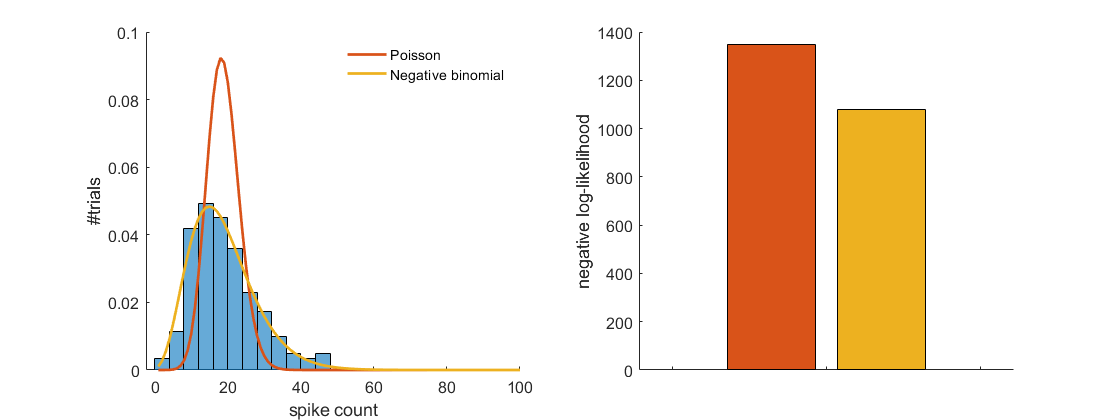

% fit poisson
lambda = poissfit(dat.count);

% fit gain-variability
gv = GainVariability(dat.count');
gv = gv.fit;

% evaluate model fits
xval = 1:100;
yval_poiss = poisspdf(xval,lambda);
nbinom_pmf = gv.pmf(xval);

% plot
figure(2),clf
set(gcf,'Position',get(gcf,'Position').*[1 1 2 1])
subplot(1,2,1)
hold on
histogram(dat.count,'Normalization','pdf','BinWidth',4)
h(1) = plot(xval,yval_poiss,'linew',2);
h(2) = plot(xval,nbinom_pmf.y,'linew',2);
xlabel('spike count')
ylabel('#trials')
legend(h, {'Poisson','Negative binomial'},'Box','Off')

subplot(1,2,2)
hold on
h_bar = bar(1, [gv.negloglike_poiss; gv.negloglike_nbinom]);
h_bar(1).FaceColor = h(1).Color;
h_bar(2).FaceColor = h(2).Color;
set(gca,'XTickLabel',[])
ylabel('negative log-likelihood')

## Fit negative binomial across separate conditions

Different experimental conditions might drive the neurons that we record from differently, resulting in varying mean spike rates and variances across conditions. 

The idea is that the parameter λ in the Poisson distribution is conditional, i.e. context dependent. The mean spike rate λ is for instance dependent on what visual stimulus has been shown (for a visual neuron). This parameter might thus differ depending on the different circumstances (conditions) of the experiment. The negative binomial distribution can be used for over-dispersed count data, that is when the conditional variance exceeds the conditional mean. It can be considered as a generalization of the Poisson distribution since it has the same mean structure as a Poisson distribution and it has an extra parameter to model the over-dispersion.

Here, the dispersion (gain variability) is assumed to reflect stimulus/condition-independent excitability fluctuations (e.g. influenced by cortical state, arousal, attention, neuromodulatory tone, etc.). To illustrate this, I plot the mean-to-variance relationship for each condition and fit a single dispersion parameter across different conditions (each individual marker). On top of this, I plot the predicted mean-to-variance relationship based on the negative binomial fit across the conditions. As you can see the predicted mean-to-variance relationship closely matches the observed data for each of the conditions. Note that under Poisson assumptions, the markers would lie on the unity line. 

% git single gain variability parameter across different conditions
gv = GainVariability(dat);
gv = gv.fit;

% get/print stats for each condition
dat_grp = grpstats(dat,{'condition'},{'min','max','median','mean','var'},'DataVars','count');
disp(dat_grp)

         condition    GroupCount    min_count    max_count    median_count    mean_count    var_count
         _________    __________    _________    _________    ____________    __________    _________

    1        1            50            6           46            20.5           22.16       98.382  
    2        2            52            3           44            14.5          15.731       56.083  
    3        3            49            3           36              16          16.796       52.332  
    4        4            52            2           43            20.5          22.365       106.55  
    5        5            50            3           34          

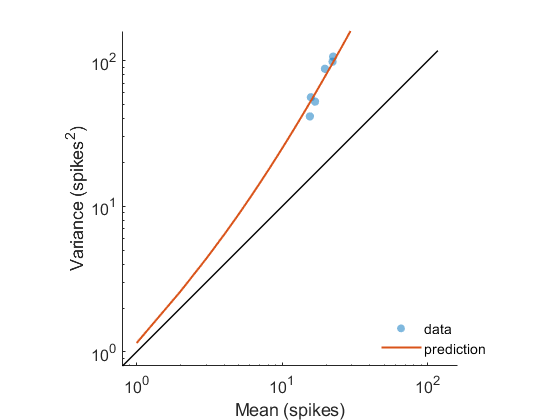


% mean and variance
mus = gv.mus;
s2s = gv.s2s;

% predicted variance based on dispersion parameter fit
m2v = gv.pred_variance;

% plot
figure(3),clf
hold on
h = scatter(mus,s2s,40,'filled','MarkerFaceAlpha',0.5);
plot(m2v.mean,m2v.variance,'linew',1.5);
legend({'data','prediction'},'AutoUpdate',"off",'Location',"best",'Box',"off")
xlim([0.8 max(s2s)*1.5])
ylim([0.8 max(s2s)*1.5])
plot([1e-10 max(s2s)*1.1],[1e-10 max(s2s)*1.1],'k','linew',1)
set(gca,'xscale','log','yscale','log')
xlabel('Mean (spikes)')
ylabel('Variance (spikes^2)')
axis square

## Data

These data are from an example unit recorded during an attention task described in [this paper](https://www.biorxiv.org/content/10.1101/2020.05.15.097675v1). 